# SBT_CCW.mat Data Cleaning

Simple Box Test, Counter-Clock Wise

David Olson

04 Sep 2021

% Start Fresh
close all
clear all
clc

% Define Constants
Fs = 50; % Hz - confirmed via hand-written notes
dt = 1 / Fs;
init_time = 13.5; % Time spent sitting still before test for initialization

% Load Raw Data
load("SBT_CCW_raw.mat")

## Accelerometer Data Cleaning

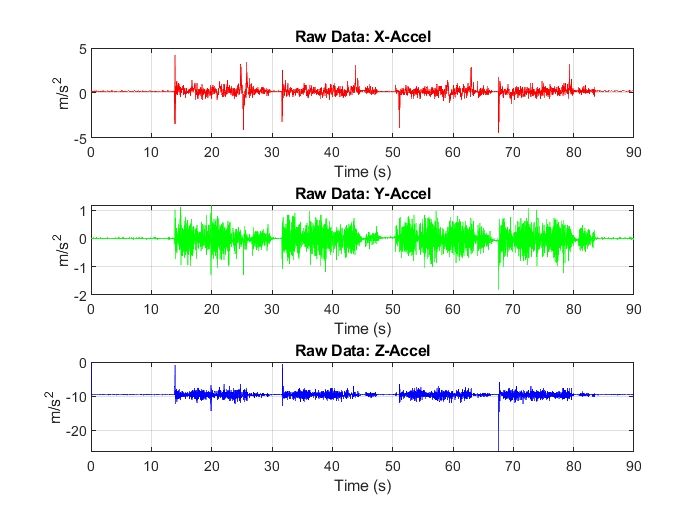

% Plot Data to see how it looks
figure(1)
subplot(3,1,1)
plot(t, accel(:,1), 'r')
title('Raw Data: X-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,2)
plot(t, accel(:,2), 'g')
title('Raw Data: Y-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on
subplot(3,1,3)
plot(t, accel(:,3), 'b')
title('Raw Data: Z-Accel')
xlabel('Time (s)')
ylabel('m/s^2')
grid on

**Data looks good, no need for adjustment**

## Gyroscope Data Cleaning

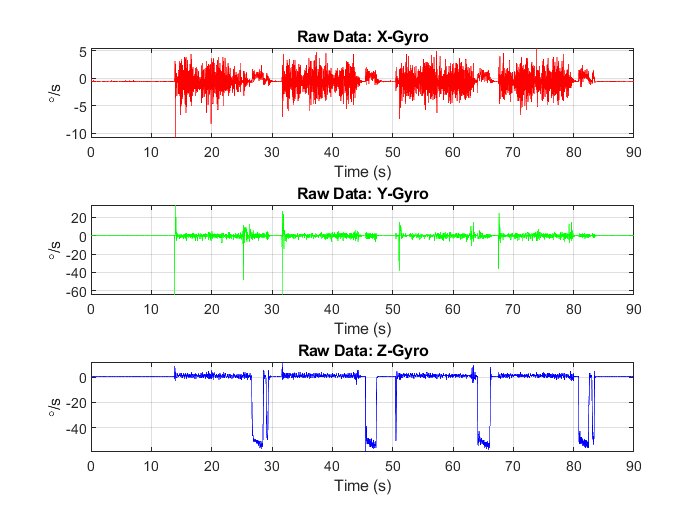

% Plot Data to see how it looks
figure(2)
subplot(3,1,1)
plot(t, gyro(:,1) * 180/pi, 'r')
title('Raw Data: X-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,2)
plot(t, gyro(:,2) * 180/pi, 'g')
title('Raw Data: Y-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on
subplot(3,1,3)
plot(t, gyro(:,3) * 180/pi, 'b')
title('Raw Data: Z-Gyro')
xlabel('Time (s)')
ylabel('\circ/s')
grid on

**Data looks good, no need for adjustment**

Y-gyro spikes hard as expected with tilt from the robot

## Odometry Data Cleaning

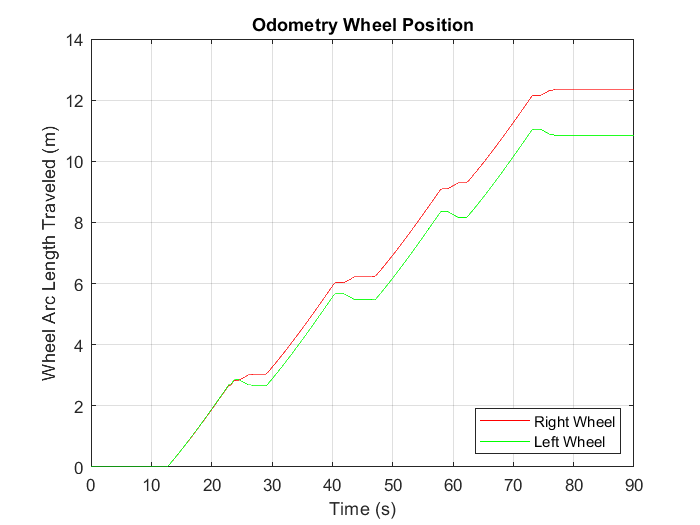

figure(3)
plot(t, odo(:,1), 'r', t, odo(:,2), 'g')
title('Odometry Wheel Position')
xlabel('Time (s)')
ylabel('Wheel Arc Length Traveled (m)')
legend('Right Wheel', 'Left Wheel', 'Location', "SouthEast")
grid on

**Data looks good, no need for adjustment**

## **Depth Camera Data Cleaning**

   
% Pre-Allocate
[kinect_samples, ~] = size(depth);
numPoints = 5000;
xyz = zeros(3, numPoints, kinect_samples);

% Convert to XYZ with down-sampling
tic
for k = 2 : kinect_samples
    xyz(:,:,k) = depth2xyz(depth, numPoints, k);
end
toc

Elapsed time is 7.252608 seconds.


## Depth Camera Animation

% % Show Animation
% for k = 2 : kinect_samples
%     
%     figure
%     hold on
%     plot3(xyz(1,:,k), xyz(2,:,k), xyz(3,:,k), 'b.');
%     viscircles([0,0], 0.35, 'Color', 'k');
%     quiver3(0,0,0,0.5,0,0, 'Color', 'r', 'LineWidth', 3);
%     title(['Kinect Point Cloud:   t = ', num2str(k)])
%     xlabel('X (m)')
%     ylabel('Y (m)')
%     zlabel('Z (m)')
%     xlim([-0.5 3.5])
%     
%     axis equal
%     view([-156.521 13.341])
%     grid on
%     hold off
%     
% %     pause(1)
%     
% %     dummy = input('Hit Enter to Move to Next Frame, Hit Q to Quit:  ', "s");
% %     if (dummy == 'Q')
% %         break
% %     end
% %     clf(4)
% %     clc
%     
% end

% Establish Point Cloud Processing Parameters
[~, K, num_frames] = size(xyz);

% Convert 3D Matrix into Cell Array
new_xyz = cell(num_frames,1);
for n = 1 : num_frames
    new_xyz{n} = xyz(:,:,n);
end
xyz = new_xyz;

## Separate Point Cloud Data into Wall and Floor Points

% Define Thresholds
x_thres = 1.5;
z_thres = 0;

% Separate Points
xyz_wall = cell(num_frames,1);
xyz_floor = cell(num_frames,1);

for n = 2 : num_frames
    
    % Remove all {0;0;0] measurements
    zero_mask = logical(sum(xyz{n}) ~= 0);
    xyz{n} = xyz{n}(:,zero_mask);
    
    % Locate and Store floor points
    floor_mask = (xyz{n}(1,:) < x_thres) & (xyz{n}(3,:) < z_thres);
    xyz_floor{n} = xyz{n}(:,floor_mask);
    
    % Locate and Store wall points
    wall_mask = (xyz{n}(3,:) >= z_thres);
    xyz_wall{n} = xyz{n}(:,wall_mask);
    
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Thresholding
test_point_cloud_flag = false;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz{test_frame}, ['Full Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
end

## Verify the attitude of the floor with a quick test case

% % Verify Good Floor Data
% test_frame = 22;
% plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
% % Pitch of two Example Points
% atan2(-0.03661 - -0.03142, 1.316 - 0.4602) * 180/pi
% % Accomplish Crude Prediction of "Ground Truth" Pitch Values
% pitch = zeros(1, num_frames);
% for n = 2 : num_frames
%     
%     % Grab and Average All Points between x = 0.5 & x = 0.6
%     xyz_floor_back_mask = (xyz_floor{n}(1,:) > 0.5) & (xyz_floor{n}(1,:) < 0.6);
%     xyz_back_avg = mean(xyz_floor{n}(:,xyz_floor_back_mask)')';
%     
%     % Grab and Average All Points between x = 0.9 & x = 0.1
%     xyz_floor_front_mask = (xyz_floor{n}(1,:) > 0.9) & (xyz_floor{n}(1,:) < 1);
%     xyz_front_avg = mean(xyz_floor{n}(:,xyz_floor_front_mask)')';
%     
%     pitch(n) = atan2(xyz_front_avg(3) - xyz_back_avg(3), xyz_front_avg(1) - xyz_back_avg(1));
%     
% end
% 
% % Plot "Ground Truth" Estimate of Pitch
% plot(2:num_frames, pitch(2:end) * 180/pi, 'g*')
% title('"Ground Truth" Pitch Guesses')
% xlabel('Frames')
% xlim([2 num_frames])
% ylabel('Pitch (\circ)')
% grid on

## Shift Wall and Floor Point Clouds to the Origin

% Locate and Shift each floor point cloud to the origin
% for n = 2 : num_frames
% %     x_max = max(xyz_floor{n}(1,:));
% %     x_min = min(xyz_floor{n}(1,:));
% %     x_shift = x_min + ((x_max - x_min)/2);
% %     y_max = max(xyz_floor{n}(2,:));
% %     y_min = min(xyz_floor{n}(2,:));
% %     y_shift = y_min + ((y_max - y_min)/2);
%     xyz_floor{n} = xyz_floor{n} - [0.5; 0; 0];
% end
% 
% Locate and Shift each wall point cloud to the origin
for n = 2 : num_frames
    x_max = max(xyz_wall{n}(1,:));
    x_min = min(xyz_wall{n}(1,:));
    x_shift = x_min + ((x_max - x_min)/2);
    xyz_wall{n} = xyz_wall{n} - [x_shift; 0; 0];
end

% - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - - -
% Test Point Cloud Shifting
test_point_cloud_flag = false;

if (test_point_cloud_flag == true)
    test_frame = 22;
    plot_point_cloud(xyz_wall{test_frame}, ['Wall Only Point Cloud at t = ', num2str(test_frame), 's'])
    hold on
    plot_point_cloud(xyz_floor{test_frame}, ['Floor Only Point Cloud at t = ', num2str(test_frame), 's'])
%     quiver3(0,0,0,cos(3*pi/180),0,sin(3*pi/180))
    hold off
end

## Complete the SNHT Floor Search

Searching for pitch only!

Begin Processing Frame #2

Elapsed time is 1.320524 seconds.


Begin Processing Frame #3

Elapsed time is 1.306261 seconds.


Begin Processing Frame #4

Elapsed time is 1.297892 seconds.


Begin Processing Frame #5

Elapsed time is 1.320562 seconds.


Begin Processing Frame #6

Elapsed time is 1.335455 seconds.


Begin Processing Frame #7

Elapsed time is 1.336374 seconds.


Begin Processing Frame #8

Elapsed time is 1.339908 seconds.


Begin Processing Frame #9

Elapsed time is 1.318788 seconds.


Begin Processing Frame #10

Elapsed time is 1.319608 seconds.


Begin Processing Frame #11

Elapsed time is 1.314620 seconds.


Begin Processing Frame #12

Elapsed time is 1.304898 seconds.


Begin Processing Frame #13

Elapsed time is 1.324723 seconds.


Begin Processing Frame #14

Elapsed time is 1.332126 seconds.


Begin Processing Frame #15

Elapsed time is 1.329072 seconds.


Begin Processing Frame #16

Elapsed time is 1.301001 seconds.


Begin Processing Frame #17

Elapsed time is 1.267524 seconds.


Begin Processing Frame #18

Elapsed time is 1.057586 seconds.


Begin Processing Frame #19

Elapsed time is 1.040226 seconds.


Begin Processing Frame #20

Elapsed time is 1.030345 seconds.


Begin Processing Frame #21

Elapsed time is 1.019309 seconds.


Begin Processing Frame #22

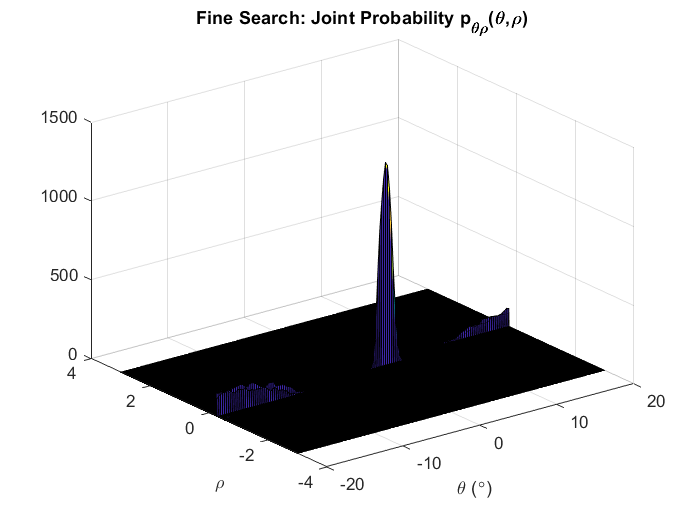

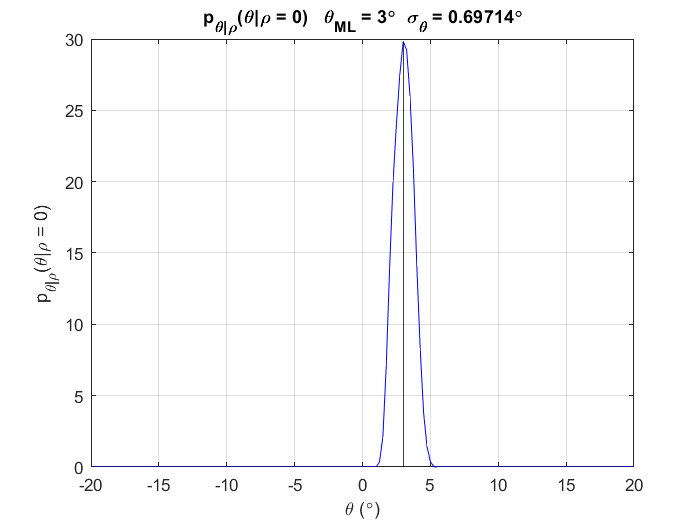

Elapsed time is 1.172388 seconds.


Begin Processing Frame #23

Elapsed time is 0.927342 seconds.


Begin Processing Frame #24

Elapsed time is 0.937443 seconds.


Begin Processing Frame #25

Elapsed time is 0.861817 seconds.


Begin Processing Frame #26

Elapsed time is 0.773290 seconds.


Begin Processing Frame #27

Elapsed time is 0.850882 seconds.


Begin Processing Frame #28

Elapsed time is 1.187807 seconds.


Begin Processing Frame #29

Elapsed time is 1.349084 seconds.


Begin Processing Frame #30

Elapsed time is 1.346818 seconds.


Begin Processing Frame #31

Elapsed time is 1.346307 seconds.


Begin Processing Frame #32

Elapsed time is 1.345865 seconds.


Begin Processing Frame #33

Elapsed time is 1.386307 seconds.


Begin Processing Frame #34

Elapsed time is 1.310960 seconds.


Begin Processing Frame #35

Elapsed time is 1.032592 seconds.


Begin Processing Frame #36

Elapsed time is 1.055340 seconds.


Begin Processing Frame #37

Elapsed time is 1.002017 seconds.


Begin Processing Frame #38

Elapsed time is 1.032529 seconds.


Begin Processing Frame #39

Elapsed time is 0.991311 seconds.


Begin Processing Frame #40

Elapsed time is 0.913403 seconds.


Begin Processing Frame #41

Elapsed time is 0.942215 seconds.


Begin Processing Frame #42

Elapsed time is 0.787965 seconds.


Begin Processing Frame #43

Elapsed time is 0.701112 seconds.


Begin Processing Frame #44

Elapsed time is 0.764906 seconds.


Begin Processing Frame #45

Elapsed time is 0.965738 seconds.


Begin Processing Frame #46

Elapsed time is 1.358137 seconds.


Begin Processing Frame #47

Elapsed time is 1.350827 seconds.


Begin Processing Frame #48

Elapsed time is 1.311386 seconds.


Begin Processing Frame #49

Elapsed time is 1.402830 seconds.


Begin Processing Frame #50

Elapsed time is 1.361049 seconds.


Begin Processing Frame #51

Elapsed time is 1.381430 seconds.


Begin Processing Frame #52

Elapsed time is 1.184429 seconds.


Begin Processing Frame #53

Elapsed time is 1.062813 seconds.


Begin Processing Frame #54

Elapsed time is 1.030711 seconds.


Begin Processing Frame #55

Elapsed time is 1.088580 seconds.


Begin Processing Frame #56

Elapsed time is 1.031910 seconds.


Begin Processing Frame #57

Elapsed time is 1.002169 seconds.


Begin Processing Frame #58

Elapsed time is 0.912068 seconds.


Begin Processing Frame #59

Elapsed time is 0.947610 seconds.


Begin Processing Frame #60

Elapsed time is 0.819308 seconds.


Begin Processing Frame #61

Elapsed time is 0.730271 seconds.


Begin Processing Frame #62

Elapsed time is 0.962497 seconds.


Begin Processing Frame #63

Elapsed time is 1.418150 seconds.


Begin Processing Frame #64

Elapsed time is 1.356127 seconds.


Begin Processing Frame #65

Elapsed time is 1.368309 seconds.


Begin Processing Frame #66

Elapsed time is 1.374148 seconds.


Begin Processing Frame #67

Elapsed time is 1.292168 seconds.


Begin Processing Frame #68

Elapsed time is 1.065119 seconds.


Begin Processing Frame #69

Elapsed time is 1.076930 seconds.


Begin Processing Frame #70

Elapsed time is 1.031217 seconds.


Begin Processing Frame #71

Elapsed time is 0.986239 seconds.


Begin Processing Frame #72

Elapsed time is 0.943871 seconds.


Begin Processing Frame #73

Elapsed time is 0.872125 seconds.


Begin Processing Frame #74

Elapsed time is 0.950088 seconds.


Begin Processing Frame #75

Elapsed time is 0.789284 seconds.


Begin Processing Frame #76

Elapsed time is 0.707029 seconds.


Begin Processing Frame #77

Elapsed time is 0.817220 seconds.


Begin Processing Frame #78

Elapsed time is 1.181975 seconds.


Begin Processing Frame #79

Elapsed time is 1.418438 seconds.


Begin Processing Frame #80

Elapsed time is 1.422537 seconds.


Begin Processing Frame #81

Elapsed time is 1.480336 seconds.


Begin Processing Frame #82

Elapsed time is 1.435237 seconds.


Begin Processing Frame #83

Elapsed time is 1.434797 seconds.


Begin Processing Frame #84

Elapsed time is 1.426067 seconds.


Begin Processing Frame #85

Elapsed time is 1.445875 seconds.


Begin Processing Frame #86

Elapsed time is 1.385451 seconds.


Begin Processing Frame #87

Elapsed time is 1.405510 seconds.


Begin Processing Frame #88

Elapsed time is 1.393349 seconds.


Begin Processing Frame #89

Elapsed time is 1.413289 seconds.


Begin Processing Frame #90

Elapsed time is 1.434750 seconds.


Begin Processing Frame #91

Elapsed time is 1.411819 seconds.


% Pre-Allocate Memory
theta_meas = zeros(1,91);
theta_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [theta_meas(n), theta_sigmas(n)] = SNHT_pitch(xyz_floor{n}, plot_flag);
    toc
    
end

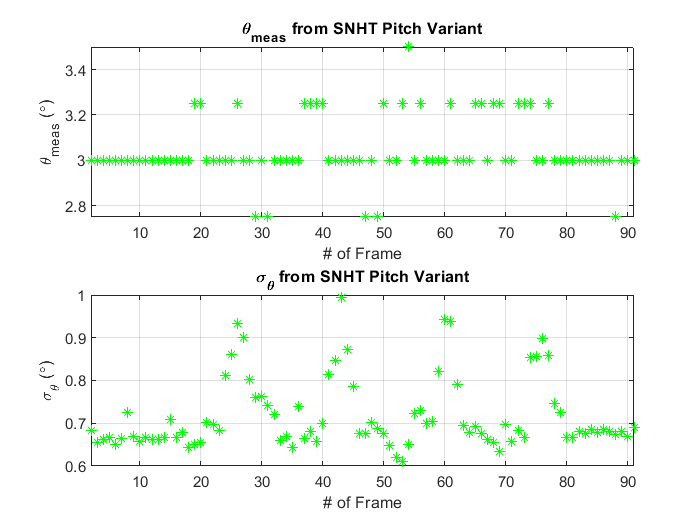

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, theta_meas * 180/pi, 'g*')
title('\theta_m_e_a_s from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\theta_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, theta_sigmas * 180/pi, 'g*')
title('\sigma_\theta from SNHT Pitch Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\theta (\circ)')
grid on

## Process Wall Point Clouds

Begin Processing Frame #2

Elapsed time is 0.691632 seconds.


Begin Processing Frame #3

Elapsed time is 0.698310 seconds.


Begin Processing Frame #4

Elapsed time is 0.708665 seconds.


Begin Processing Frame #5

Elapsed time is 0.632440 seconds.


Begin Processing Frame #6

Elapsed time is 0.639884 seconds.


Begin Processing Frame #7

Elapsed time is 0.619809 seconds.


Begin Processing Frame #8

Elapsed time is 0.606641 seconds.


Begin Processing Frame #9

Elapsed time is 0.676009 seconds.


Begin Processing Frame #10

Elapsed time is 0.620461 seconds.


Begin Processing Frame #11

Elapsed time is 0.633866 seconds.


Begin Processing Frame #12

Elapsed time is 0.701176 seconds.


Begin Processing Frame #13

Elapsed time is 0.695050 seconds.


Begin Processing Frame #14

Elapsed time is 0.583404 seconds.


Begin Processing Frame #15

Elapsed time is 0.583528 seconds.


Begin Processing Frame #16

Elapsed time is 0.667325 seconds.


Begin Processing Frame #17

Elapsed time is 0.860115 seconds.


Begin Processing Frame #18

Elapsed time is 2.145453 seconds.


Begin Processing Frame #19

Elapsed time is 1.924793 seconds.


Begin Processing Frame #20

Elapsed time is 2.025084 seconds.


Begin Processing Frame #21

Elapsed time is 2.581018 seconds.


Begin Processing Frame #22

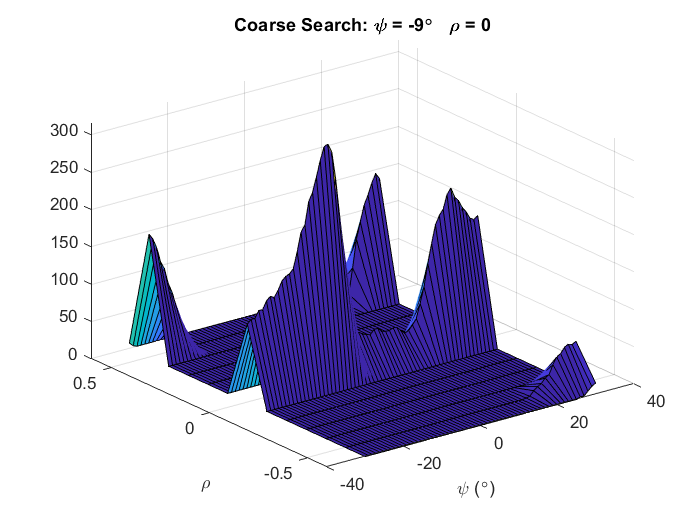

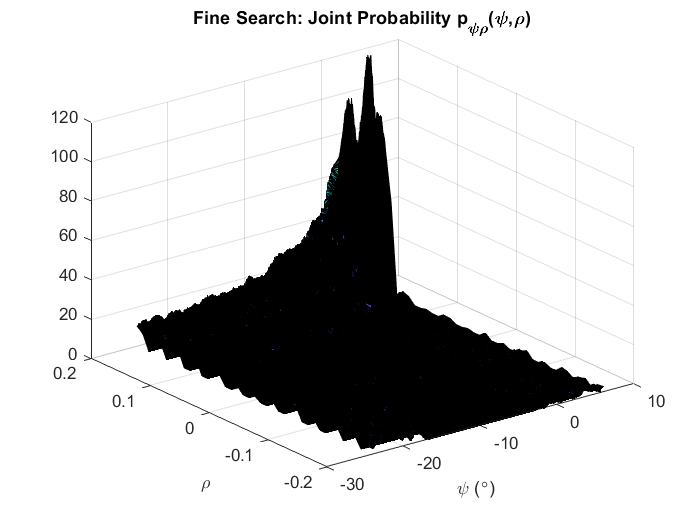

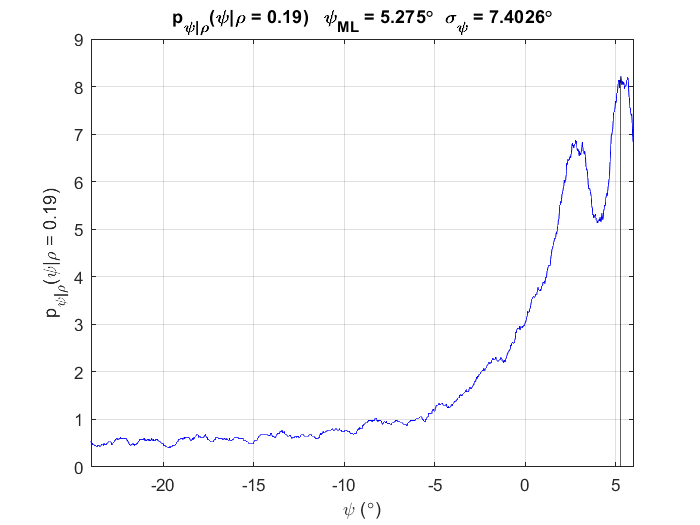

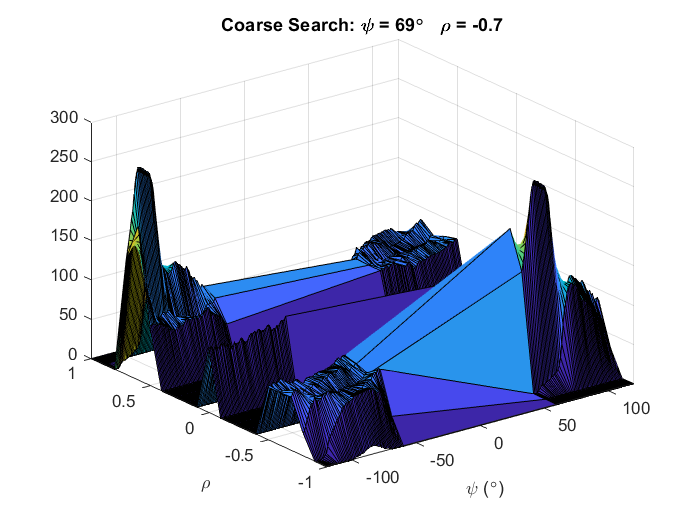

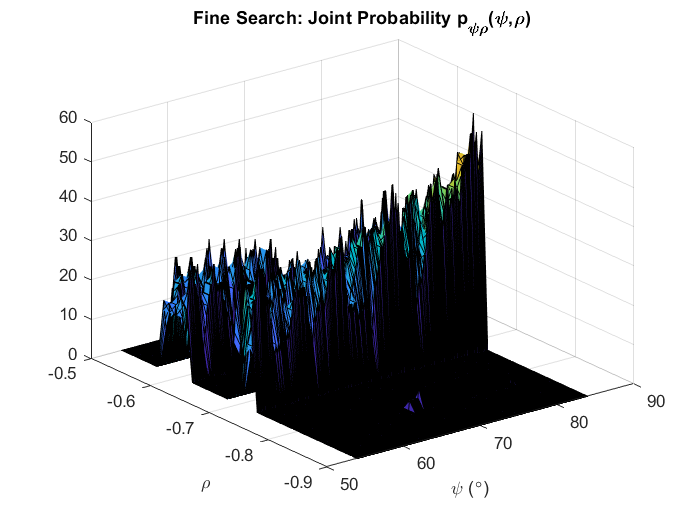

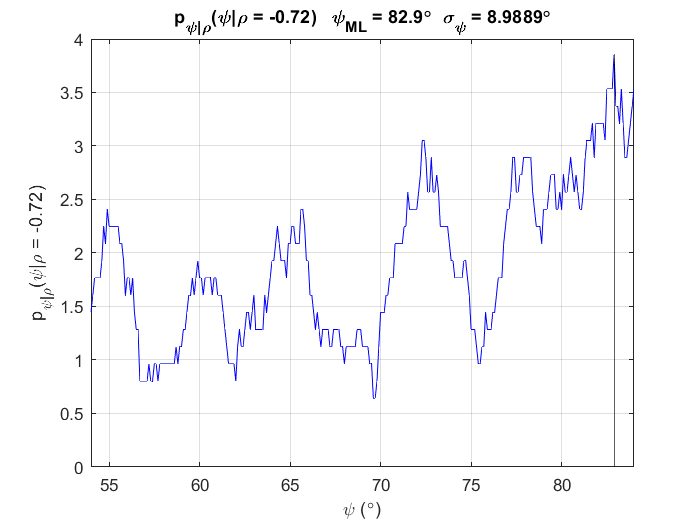

Elapsed time is 3.175793 seconds.


Begin Processing Frame #23

Elapsed time is 2.871522 seconds.


Begin Processing Frame #24

Elapsed time is 3.290856 seconds.


Begin Processing Frame #25

Elapsed time is 3.953488 seconds.


Begin Processing Frame #26

Elapsed time is 4.402520 seconds.


Begin Processing Frame #27

Elapsed time is 3.993470 seconds.


Begin Processing Frame #28

Elapsed time is 1.435490 seconds.


Begin Processing Frame #29

Elapsed time is 0.376308 seconds.


Begin Processing Frame #30

Elapsed time is 0.397475 seconds.


Begin Processing Frame #31

Elapsed time is 0.370389 seconds.


Begin Processing Frame #32

Elapsed time is 0.431329 seconds.


Begin Processing Frame #33

Elapsed time is 0.468104 seconds.


Begin Processing Frame #34

Elapsed time is 0.536035 seconds.


Begin Processing Frame #35

Elapsed time is 1.928268 seconds.


Begin Processing Frame #36

Elapsed time is 1.773665 seconds.


Begin Processing Frame #37

Elapsed time is 1.992525 seconds.


Begin Processing Frame #38

Elapsed time is 2.308471 seconds.


Begin Processing Frame #39

Elapsed time is 2.432426 seconds.


Begin Processing Frame #40

Elapsed time is 2.809982 seconds.


Begin Processing Frame #41

Elapsed time is 3.380505 seconds.


Begin Processing Frame #42

Elapsed time is 4.334559 seconds.


Begin Processing Frame #43

Elapsed time is 5.011273 seconds.


Begin Processing Frame #44

Elapsed time is 4.641034 seconds.


Begin Processing Frame #45

Elapsed time is 3.294381 seconds.


Begin Processing Frame #46

Elapsed time is 0.668420 seconds.


Begin Processing Frame #47

Elapsed time is 0.674921 seconds.


Begin Processing Frame #48

Elapsed time is 0.762547 seconds.


Begin Processing Frame #49

Elapsed time is 0.438873 seconds.


Begin Processing Frame #50

Elapsed time is 0.504372 seconds.


Begin Processing Frame #51

Elapsed time is 0.493807 seconds.


Begin Processing Frame #52

Elapsed time is 1.834338 seconds.


Begin Processing Frame #53

Elapsed time is 1.968463 seconds.


Begin Processing Frame #54

Elapsed time is 2.025329 seconds.


Begin Processing Frame #55

Elapsed time is 2.293877 seconds.


Begin Processing Frame #56

Elapsed time is 2.432853 seconds.


Begin Processing Frame #57

Elapsed time is 2.643993 seconds.


Begin Processing Frame #58

Elapsed time is 2.910973 seconds.


Begin Processing Frame #59

Elapsed time is 3.500730 seconds.


Begin Processing Frame #60

Elapsed time is 4.328425 seconds.


Begin Processing Frame #61

Elapsed time is 5.058119 seconds.


Begin Processing Frame #62

Elapsed time is 3.057428 seconds.


Begin Processing Frame #63

Elapsed time is 0.429592 seconds.


Begin Processing Frame #64

Elapsed time is 0.438305 seconds.


Begin Processing Frame #65

Elapsed time is 0.374893 seconds.


Begin Processing Frame #66

Elapsed time is 0.421764 seconds.


Begin Processing Frame #67

Elapsed time is 0.855190 seconds.


Begin Processing Frame #68

Elapsed time is 1.888223 seconds.


Begin Processing Frame #69

Elapsed time is 1.904615 seconds.


Begin Processing Frame #70

Elapsed time is 2.169400 seconds.


Begin Processing Frame #71

Elapsed time is 2.396369 seconds.


Begin Processing Frame #72

Elapsed time is 2.547982 seconds.


Begin Processing Frame #73

Elapsed time is 3.112146 seconds.


Begin Processing Frame #74

Elapsed time is 3.541990 seconds.


Begin Processing Frame #75

Elapsed time is 4.454243 seconds.


Begin Processing Frame #76

Elapsed time is 4.931414 seconds.


Begin Processing Frame #77

Elapsed time is 4.147945 seconds.


Begin Processing Frame #78

Elapsed time is 1.820710 seconds.


Begin Processing Frame #79

Elapsed time is 0.224160 seconds.


Begin Processing Frame #80

Elapsed time is 0.231459 seconds.


Begin Processing Frame #81

Elapsed time is 0.240553 seconds.


Begin Processing Frame #82

Elapsed time is 0.260045 seconds.


Begin Processing Frame #83

Elapsed time is 0.233286 seconds.


Begin Processing Frame #84

Elapsed time is 0.237312 seconds.


Begin Processing Frame #85

Elapsed time is 0.235180 seconds.


Begin Processing Frame #86

Elapsed time is 0.239175 seconds.


Begin Processing Frame #87

Elapsed time is 0.209269 seconds.


Begin Processing Frame #88

Elapsed time is 0.243898 seconds.


Begin Processing Frame #89

Elapsed time is 0.258520 seconds.


Begin Processing Frame #90

Elapsed time is 0.253123 seconds.


Begin Processing Frame #91

Elapsed time is 0.195229 seconds.


% Pre-Allocate Memory
psi_fw_meas = zeros(1,91);
psi_fw_sigmas = zeros(1,91);
psi_sw_meas = zeros(1,91);
psi_sw_sigmas = zeros(1,91);

% Run SNHT pitch algorithm
test_frame = 22;
for n = 2 : num_frames
    
    % Select Test Frame to Plot
    if (n == test_frame)
        plot_flag = true;
    else
        plot_flag = false;
    end
    
    % Run SNHT Pitch
    fprintf(['Begin Processing Frame #', num2str(n)])
    tic 
    [psi_fw_meas(n), psi_fw_sigmas(n)] = SNHT_front_wall(xyz_wall{n}, plot_flag);
    [psi_sw_meas(n), psi_sw_sigmas(n)] = SNHT_side_wall(xyz_wall{n}, plot_flag);
    toc
    
end

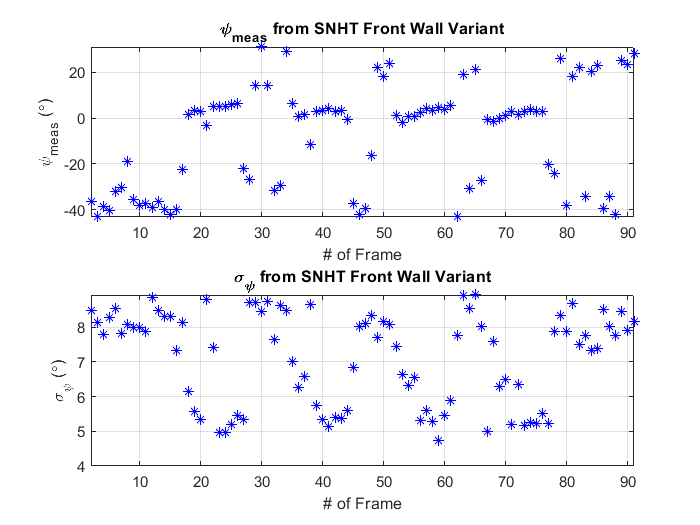

% Plot Results
figure
subplot(2,1,1)
plot(1:num_frames, psi_fw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_fw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Front Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

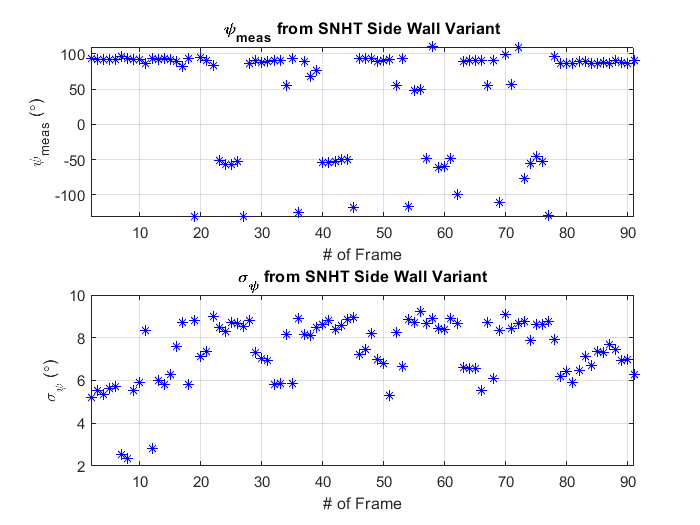

figure
subplot(2,1,1)
plot(1:num_frames, psi_sw_meas * 180/pi, 'b*')
title('\psi_m_e_a_s from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_sw_sigmas * 180/pi, 'b*')
title('\sigma_\psi from SNHT Side Wall Variant')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on

## Save Data

% Transpose Everything to the Same Format
t = t';
accel = accel';
gyro = gyro';
odo = odo';

% Save to Structure
P.Fs = Fs;                         % Hz
P.dt = dt;                         % s
P.t = t;                           % s
P.t_end = t(end);                  % s
P.init_time = init_time;           % s
P.accel = double(accel);           % m/s^2
P.gyro = double(gyro);             % rad/s
P.odo = odo;                       % m
P.baro = 84.5*ones(1, length(t));  % kPa -- fake measurement for now!
P.theta_meas = theta_meas;         % rad
P.theta_sigmas = theta_sigmas;     % rad
P.psi_fw_meas = psi_fw_meas;       % rad
P.psi_fw_sigmas = psi_fw_sigmas;   % rad
P.psi_sw_meas = psi_sw_meas;       % rad
P.psi_sw_sigmas = psi_sw_sigmas;   % rad

save("SBT_CCW.mat", 'P')

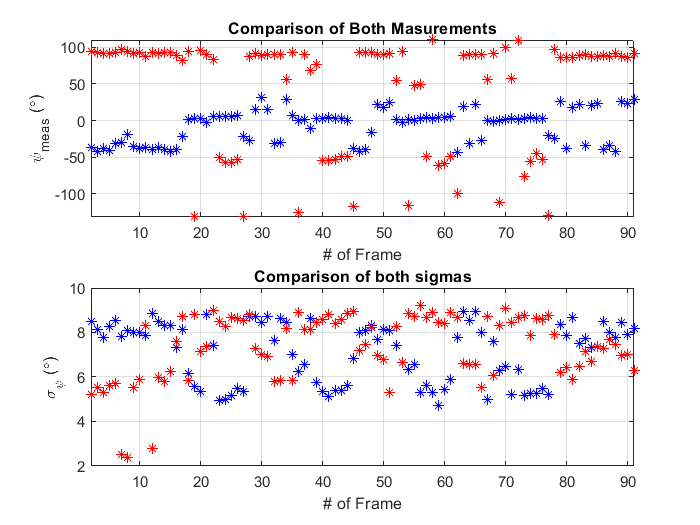

% Quick Test
figure
subplot(2,1,1)
plot(1:num_frames, psi_fw_meas * 180/pi, 'b*', 1:num_frames, psi_sw_meas * 180/pi, 'r*')
title('Comparison of Both Masurements')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\psi_m_e_a_s (\circ)')
grid on
subplot(2,1,2)
plot(1:num_frames, psi_fw_sigmas * 180/pi, 'b*', 1:num_frames, psi_sw_sigmas * 180/pi, 'r*')
title('Comparison of both sigmas')
xlabel('# of Frame')
xlim([2 num_frames])
ylabel('\sigma_\psi (\circ)')
grid on